clear all
close all

addpath("Immagini\06_binning")

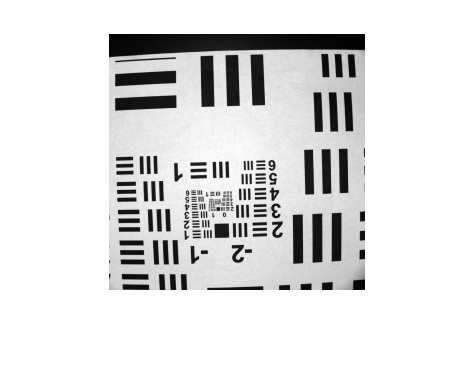

im_1 = importdata("Risoluzione_B4_t125_f4.asc");
im_1 = im_1(:,2:end);

noise_1 = importdata("Risoluzione_buio_B4_t125_f4.asc");
noise_1 = noise_1(:,2:end);

im_1 = im_1 - noise_1;

imshow(im_1,[])

x = [106  120];
y = [-204 -204];

pixel_dist = round(sqrt((x(1)-x(2))^2 + (y(1)-y(2))^2))

pixel_dist = 14

conv_factor = pixel_dist/10 % pixel/mm

conv_factor = 1.4000

close all hidden;

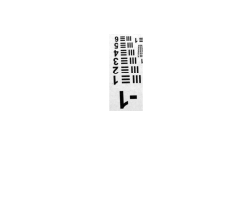

group_m1 = im_1(155:232,72:105);
imshow(group_m1, [])

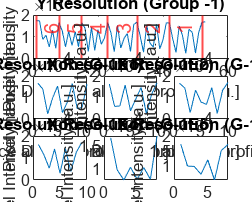


subplot(3,3,[1,2,3]);
y_resm1 = improfile(group_m1, [15 15], [1 53]);
plot(y_resm1)
title("Y Resolution (Group -1)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along y profile [a.u.]")
xline(52, 'LineWidth', 1, 'Color', 'r')
xline(42, 'LineWidth', 1, 'Color', 'r', 'Label', '1')
xline(32, 'LineWidth', 1, 'Color', 'r', 'Label', '2')
xline(23, 'LineWidth', 1, 'Color', 'r', 'Label', '3')
xline(15, 'LineWidth', 1, 'Color', 'r', 'Label', '4')
xline(8, 'LineWidth', 1, 'Color', 'r', 'Label', '5')
xline(1, 'LineWidth', 1, 'Color', 'r', 'Label', '6')

subplot(3,3,4);
x_resm11 = improfile(group_m1, [23 33], [47 47]);
plot(x_resm11)
title("X Resolution (G-1E1)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,5);
x_resm12 = improfile(group_m1, [22 31], [36 36]);
plot(x_resm12)
title("X Resolution (G-1E2)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,6);
x_resm13 = improfile(group_m1, [20 29], [27 27]);
plot(x_resm13)
title("X Resolution (G-1E3)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,7);
x_resm14 = improfile(group_m1, [19 27], [19 19]);
plot(x_resm14)
title("X Resolution (G-1E4)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,8);
x_resm15 = improfile(group_m1, [18 25], [12 12]);
plot(x_resm15)
title("X Resolution (G-1E5)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

subplot(3,3,9);
x_resm16 = improfile(group_m1, [17 24], [5 5]);
plot(x_resm16)
title("X Resolution (G-1E6)")
ylabel("Pixel Intensity [a.u.]")
xlabel("Distance along x profile [a.u.]")

group_y = -1;
element_y = 6;

r_y = 2^(group_y+(element_y-1)/6);
R_y = 1/r_y

R_y = 1.1225


group_x = -1;
element_x = 5;

r_x = 2^(group_x+(element_x-1)/6);
R_x = 1/r_x

R_x = 1.2599

half = @(x) round(x/2);